# Para M=2

clear
syms t c00 c01 c02;
assume(t,'real');
assume(c00,'real');
assume(c01,'real');
assume(c02,'real');
k=0;
n=0;

m=0;
p00 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=1;
p01 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=2;
p02=sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));

F= [0         0         0;
    3.46410162 0         0;
    0         7.74596669 0];

D = blkdiag(F);


C=[c00 ; 
    c01;
    c02];

w=[p00;
    p01;
    p02];


y1  = C'*w;
y2 = subs(y1,t,t+t/2);

dy1=vpa(C'*D*w,5);
dy2=vpa(subs(dy1,t,t-t^2),5);

dydy1=vpa(C'*(D^2)*w,5);

eq=vpa(dydy1 + dy2 - (t^2)*y2 + (dy1)^2 - dy1*y1 - exp(t) - exp(t-t^2) +t^2 * exp((3*t)/2) == 0 , 5);

eq1=subs(y1,t,0) - 1 ==0;
eq2=vpa(subs(dy1,t,0) -1 ==0,5);
eq3=vpa(subs(eq,t,0.211),5);

c0 = [0; 0; 0];

solucion = fsolve(@sistemaecuaciones, c0);

c00 = solucion(1);
c01 = solucion(2);
c02 = solucion(3);


sol1 = [c00;
        c01;
        c02];

sol2 = [1.69965459949562
        0.461583610459021
        0.044646078189552];

y = sol1'*w;
y2 = sol2'*w;


t_values = linspace(0, 1, 100);  
y_values = subs(y, {t}, t_values); 
y_gvalus = subs(y2, {t}, t_values);
clf
yt=exp(t_values);

plot(t_values,yt,'LineWidth',2)
hold on
plot(t_values, y_values,'or');
hold on
plot(t_values, y_gvalus,'ok');
xlabel('t');
ylabel('y');
legend("Teorica","LWM","NSGA-II")
hold off
indices = [1,5,10,20, 40, 80,100];

error1 = vpa(abs(y_values(indices) - yt(indices)),4)
error2 = vpa(abs(y_gvalus(indices) - yt(indices)),4)
error1-error2


# Para M=3

clear;
syms t c00 c01 c02 c03;
assume(t,'real');
assume(c00,'real');
assume(c01,'real');
assume(c02,'real');
assume(c03,'real');
k=0;
n=0;

m=0;
p00 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=1;
p01 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=2;
p02=sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=3;
p03=sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));

F= matriz_F(3,0);

D = blkdiag(F);


C=[c00 ; 
    c01;
    c02;
    c03];

w=[p00;
    p01;
    p02
    p03];


y1  = C'*w;
y2 = subs(y1,t,t+t/2);

dy1=vpa(C'*D*w,7);
dy2=vpa(subs(dy1,t,t-t^2),7);

dydy1=vpa(C'*(D^2)*w,5);

eq=vpa(dydy1 + dy2 - (t^2)*y2 + (dy1)^2 - dy1*y1 - exp(t) - exp(t-t^2) +t^2 * exp((3*t)/2) == 0 , 5);
eq1=subs(y1,t,0) - 1 == 0; 
eq2=vpa(subs(dy1,t,0) - 1 == 0,5);
eq3=vpa(subs(eq,t,0.211),5);
eq4=vpa(subs(eq,t,0.5),5);



c0 = [0; 0; 0; 0];

solucion = fsolve(@sistemaecuaciones, c0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


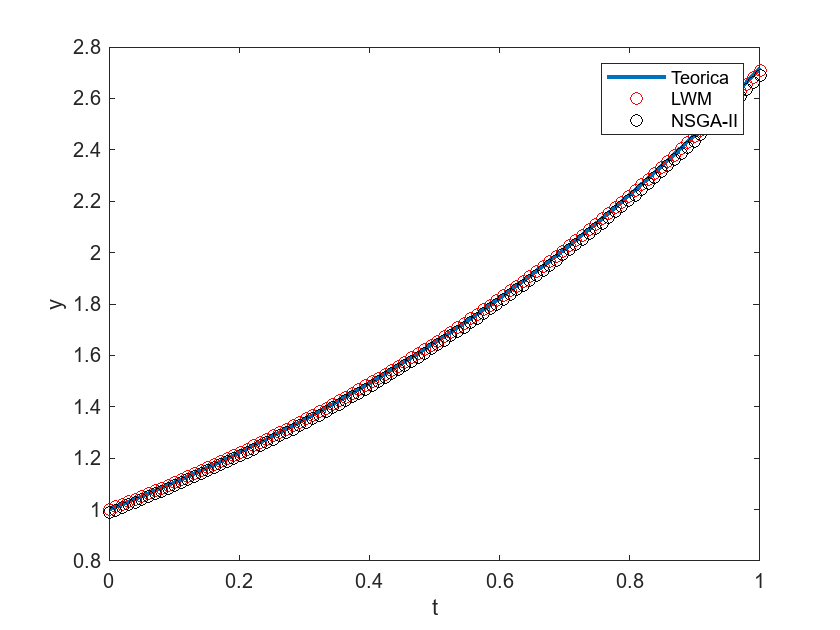


c00 = solucion(1);
c01 = solucion(2);
c02 = solucion(3);
c03 = solucion(4);

sol1 = [c00;
        c01;
        c02;
        c03];

y = sol1'*w;

sol2 =[1.701792091313211;
       0.484127292746815;
       0.060887434322195;
       0.004311360119016];
y2 = sol2'*w;

t_values = linspace(0, 1, 100);  
y_values = subs(y, {t}, t_values); 
y_gnvals = subs(y2, {t}, t_values);
clf
yt=exp(t_values);
plot(t_values,yt,'LineWidth',2)
hold on
plot(t_values, y_values,'or');
hold on
plot(t_values, y_gnvals,'ok');
xlabel('t');
ylabel('y');
legend("Teorica","LWM","NSGA-II")
hold off


indices = [1,5,10,20, 40, 80,100];

error1 = vpa(abs(y_values(indices) - yt(indices)),4)

$$error1 = \left(\begin{array}{ccccccc} -1.819e-12 & 4.037e-5 & 0.0001757 & 0.0005718 & 0.001117 & 0.002677 & 0.01073 \end{array}\right)$$

error2 = vpa(abs(y_gnvals(indices) - yt(indices)),4)

$$error2 = \left(\begin{array}{ccccccc} 0.012 & 0.01216 & 0.01243 & 0.01312 & 0.01442 & 0.01923 & 0.0304 \end{array}\right)$$

error1-error2   

$$ans = \left(\begin{array}{ccccccc} -0.01199932162489858455955982208252 & -0.012115244331653229892253875732422 & -0.012257093154403264634311199188232 & -0.012548913743557932320982217788696 & -0.013299924167313292855396866798401 & -0.016550441812796634621918201446533 & -0.019666531790790031664073467254639 \end{array}\right)$$

clear;
syms t c00 c01 c02 c03 c04 c05;
assume(t,'real');
assume(c00,'real');
assume(c01,'real');
assume(c02,'real');
assume(c03,'real');
assume(c04,'real');
assume(c05,'real');
k=0;
n=0;

m=0;
p00 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=1;
p01 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=2;
p02 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=3;
p03 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=4;
p04 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=5;
p05 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));

F= matriz_F(5,0);

D = blkdiag(F);


C=[c00 ; 
    c01;
    c02;
    c03;
    c04;
    c05];

w=[p00;
    p01;
    p02
    p03;
    p04;
    p05];


y1  = C'*w;
y2 = subs(y1,t,t+t/2);

dy1=vpa(C'*D*w,7);
dy2=vpa(subs(dy1,t,t-t^2),7);

dydy1=vpa(C'*(D^2)*w,5);

eq=vpa(dydy1 + dy2 - (t^2)*y2 + (dy1)^2 - dy1*y1 - exp(t) - exp(t-t^2) +t^2 * exp((3*t)/2) == 0 , 5);
eq1=subs(y1,t,0) - 1 == 0;
eq2=vpa(subs(dy1,t,0) - 1 ==0,5);
eq3=vpa(subs(eq,t,0.211),5);
eq4=vpa(subs(eq,t,0.5),5);
eq5=vpa(subs(eq,t,0.67),5);
eq6=vpa(subs(eq,t,0.231),5);

% Suposición inicial
c0 = [0; 0; 0; 0; 0; 0];

% Resolver el sistema de ecuaciones
solucion = fsolve(@sistemaecuaciones, c0);

% Mostrar los resultados
c00 = solucion(1);
c01 = solucion(2);
c02 = solucion(3);
c03 = solucion(4);
c04 = solucion(5);
c05 = solucion(6);

sol1 = [c00;
        c01;
        c02;
        c03;
        c04
        c05];

y = sol1'*w;



sol2 = [1.329041610414229
       0.615976133688194
       0.069990215401975
       0.095665400453494
       0.038606791997039 
       0.030806583213056];


y2 = sol2'*w;


t_values = linspace(0, 1, 100);  
y_values = subs(y, {t}, t_values); 
y_gnvals = subs(y2, {t}, t_values);
clf
yt=exp(t_values);
plot(t_values,yt,'LineWidth',2)
hold on
plot(t_values, y_values,'or');
hold on
plot(t_values, y_gnvals,'ok');
xlabel('t');
ylabel('y');
legend("Teorica","LWM","NSGA-II")
hold off

indices = [1,5,10,20, 40, 80,100];

error1 = vpa(abs(y_values(indices) - yt(indices)),4)
error2 = vpa(abs(y_gnvals(indices) - yt(indices)),4)
error1-error2